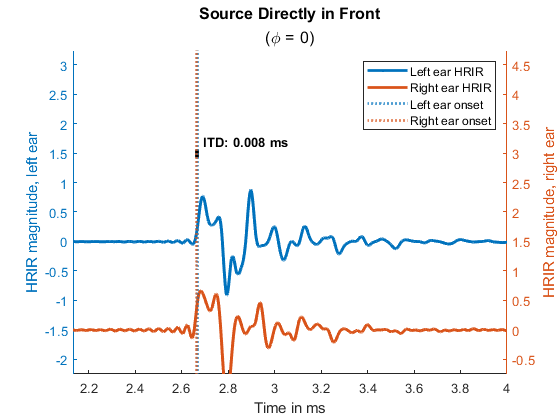

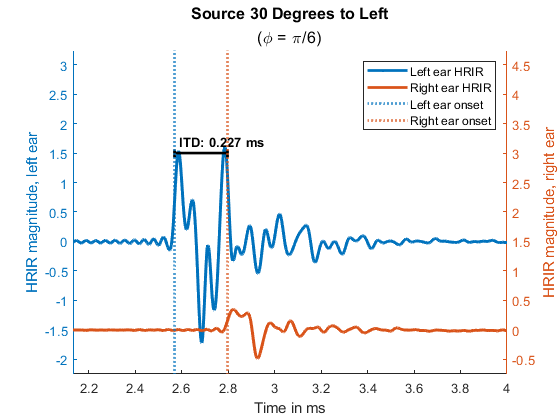

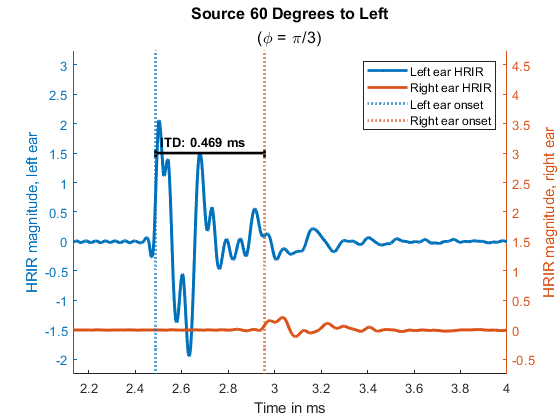

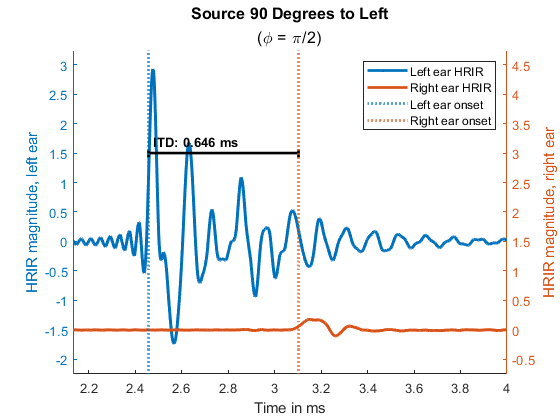

sample_rate = 48000;
sample_length = 256;
upsamp_factor = 10;
time = [1:sample_length*upsamp_factor] / ((sample_rate / 1000) * upsamp_factor);

% Directions for precomputed HRIRs that we will load
source_dirs = ["0_deg";
        "30_deg";
        "60_deg";
        "90_deg" ];

titles = ["Source Directly in Front";
        "Source 30 Degrees to Left";
        "Source 60 Degrees to Left";
        "Source 90 Degrees to Left" ];

% Precomputed ITD values from eikonal solver for these directions
eik = [1.0402999645097236e-08;
       0.0002257686380167771;
       0.00045667148970995474;
       0.0006102701241939375];

subtitles = ["(" + texlabel("phi = 0") + ")";
            "(" + texlabel("phi = pi/6") + ")";
            "(" + texlabel("phi = pi/3") + ")";
            "(" + texlabel("phi = pi/2") + ")"];

for i=1:length(source_dirs)
    
    % We know we saved the hrir variables with the names "hrir_l" and "hrir_r"
    struct = load("hrir_left_ear_" + source_dirs(i) + ".mat");
    hrir_l = struct.hrir_l;
    struct = load("hrir_right_ear_" + source_dirs(i) + ".mat");
    hrir_r = struct.hrir_r;
    hrir_l = interp(hrir_l, upsamp_factor);
    hrir_r = interp(hrir_r, upsamp_factor);
    [itd_bem, onset_l, onset_r] = get_itd(hrir_l, hrir_r, 48000*upsamp_factor, "onset", "lowpass", 1);
    
    start = floor(length(hrir_l) * 0.40);
    finish = floor(length(hrir_l) * 0.75);
    
    t_onset = time(onset_l);
    itd_bem = itd_bem * 1e3;
    itd_eik = eik(i) * 1e3;
    
    figure;
    hold on

    % Plot the actual HRIRs, one in blue the other in red, overlaid but each with their own axis so one is shown above the other
    yyaxis left
    p1 = plot(time(start:finish), hrir_l(start:finish), "LineWidth", 2); xlim([time(start) time(finish)]); ylim([-2.25 3.25]); ylabel("HRIR magnitude, left ear");
    p1.DisplayName = "Left ear HRIR";
    yyaxis right
    p2 = plot(time(start:finish), hrir_r(start:finish), "LineWidth", 2); xlim([time(start) time(finish)]); ylim([-.75 4.75]); ylabel("HRIR magnitude, right ear");
    p2.DisplayName = "Right ear HRIR";
    
    % Blue and red dotted vertical lines marking the onsets used for the ITD calculations
    clr1 = p1.Color;
    clr2 = p2.Color;
    xl1 = xline(time(onset_l), ":", "Color", clr1, "LineWidth", 2);
    xl1.DisplayName = "Left ear onset";    
    xl2 = xline(time(onset_r), ":", "Color", clr2, "LineWidth", 2);
    xl2.DisplayName = "Right ear onset";
    
    % Plot a dark black bar showing that the length of the ITD is derived from the two onsets.
    itd1 = plot([t_onset t_onset+itd_bem], [3 3], "k|-", LineWidth=2);
    txt1 = sprintf("ITD: %.3f ms", abs(itd_bem));
    text(t_onset+.02, 3.2, txt1, FontWeight="bold");
    
    % Plot another bar to indicate the ITD length computed by the eikonal solver
%     itd2 = plot([t_onset t_onset+itd_eik], [4 4], "k|-", LineWidth=2);
%     txt2 = sprintf("Eikonal ITD: %.3f ms", abs(itd_eik));
%     text(t_onset+.02, 4.2, txt2, FontWeight="bold");
    
    xlabel("Time in ms");
    title(titles(i), subtitles(i), "FontSize", 12);
    legend(p1.DisplayName, p2.DisplayName, xl1.DisplayName, xl2.DisplayName);
    
    hold off
end;